#  PROYECTO

### 1- Elegid una señal real de por ejemplo, la base de datos *https://archive.physionet.org/cgi-bin/atm/ATM *

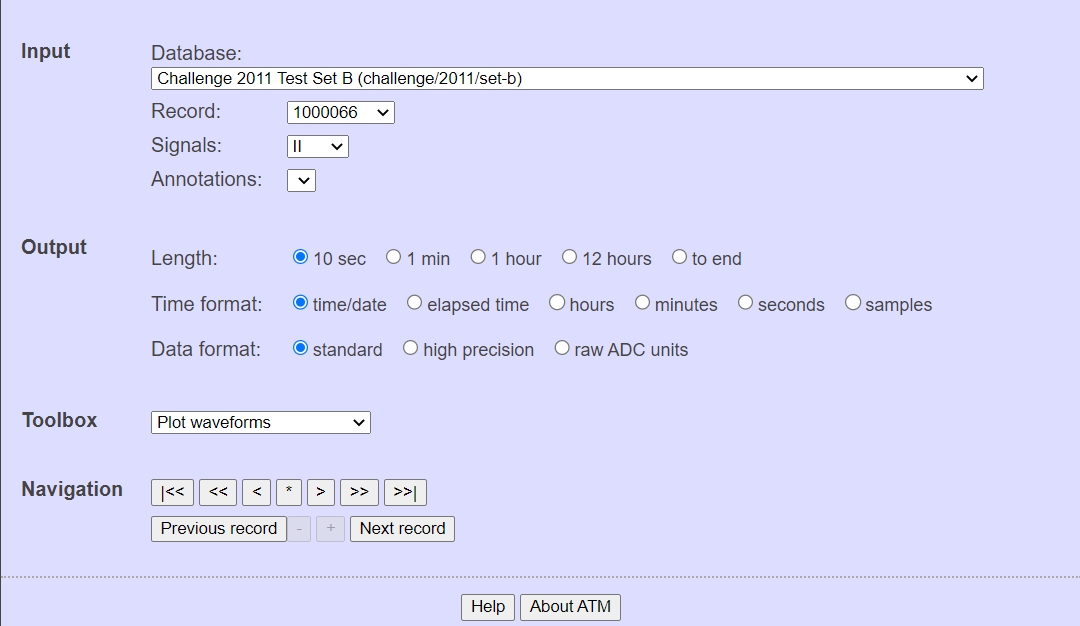

### 2- Representadla en tiempo y en frecuencia (escala analógica y discreta) 

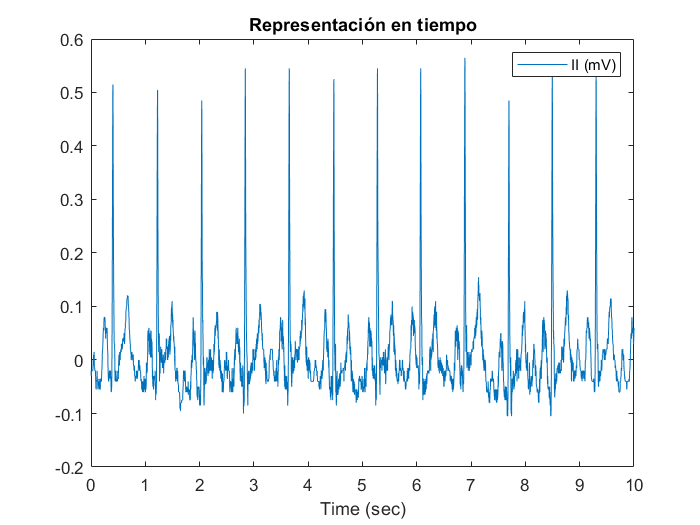

load('1000066m.mat')
plotATM('1000066m') ;title('Representación en tiempo')

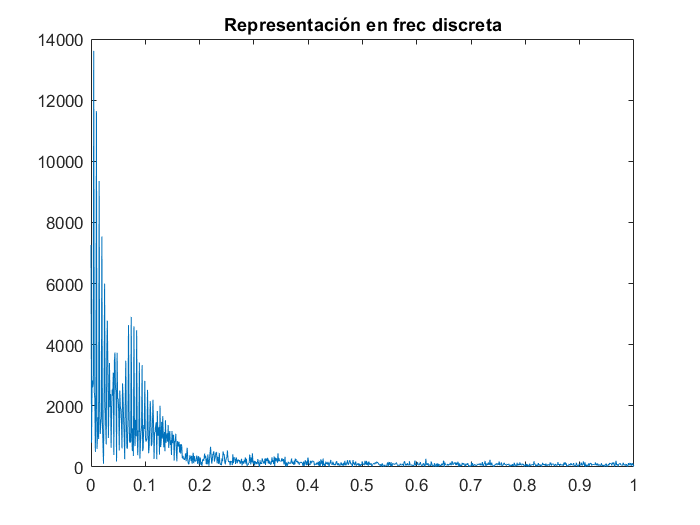

N=length(val);
t=10;
n=linspace(0,N-1,N);
w=linspace(0,pi,1000);
X=DTFT(val,n,w);
plot(w/pi,abs(X)); title('Representación en frec discreta')

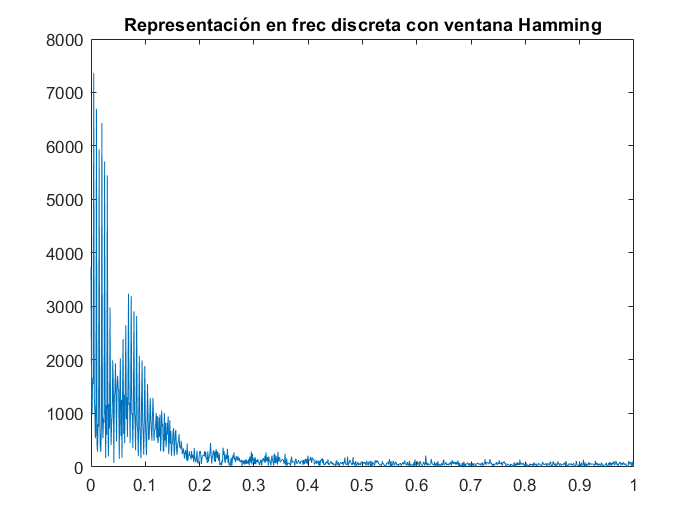

%Aplico una ventana Hamming para suavizar la señal
Xw=DTFT(val.*hamming(N)',n,w);
plot(w/pi,abs(Xw)); title('Representación en frec discreta con ventana Hamming')  %queda cerca del origen porque está muy muestreada

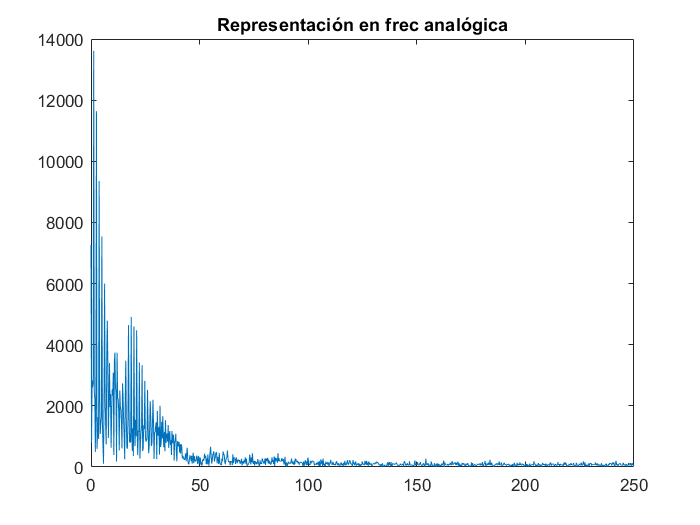

%Para representarlo en analógico
fs=N/t; %Frec de muestreo: cociente de 10s entre 5000 muestras
w_an=w*fs/(2*pi);
plot(w_an,abs(X)) ; title('Representación en frec analógica')

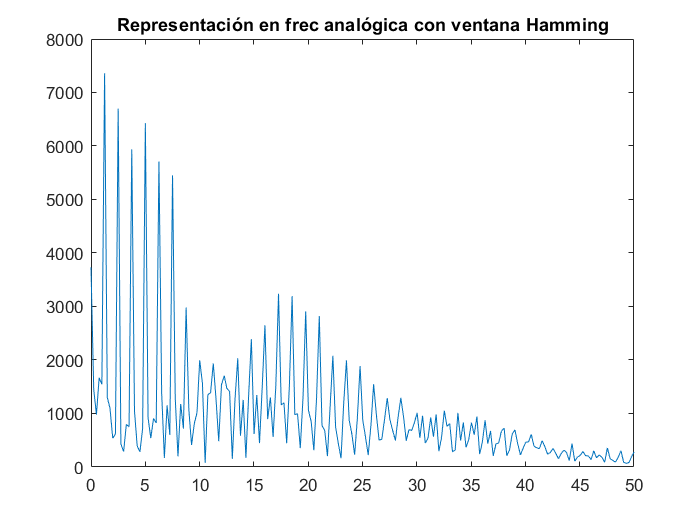

%Si le aplico una ventana y estudio más concretamente el intervalo de 0 a 50 Hz
plot(w_an,abs(Xw))
axis([0,50,0,8000]) ; title('Representación en frec analógica con ventana Hamming')

### 3-Selección de filtro IIR 

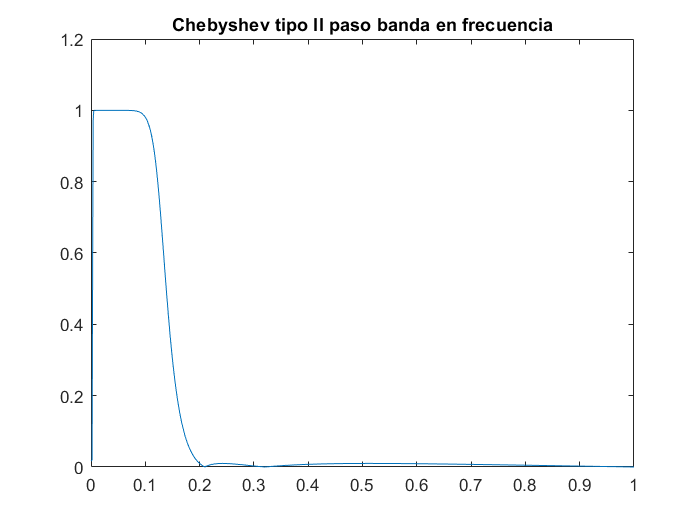

%Para la componente continua, escojo un filtro Chebychev tipo II paso banda
[b,a]=cheby2(5,40,[0.002 0.2], 'bandpass');
%para normalizar la frec de 0.5 Hz, fnorm=0.1*2/fs=0.002
%para normalizar la frec de 50 Hz, fnorm= 50*2/fs = 0.2
hc=filter(b,a,delta(n,0));
Hc=DTFT(hc,n,w);
plot(w/pi,abs(Hc)); title('Chebyshev tipo II paso banda en frecuencia')

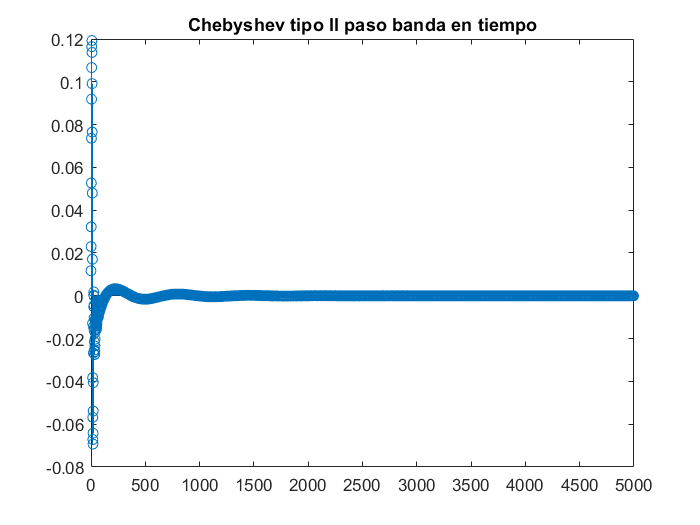

stem(n,real(hc)); title('Chebyshev tipo II paso banda en tiempo')

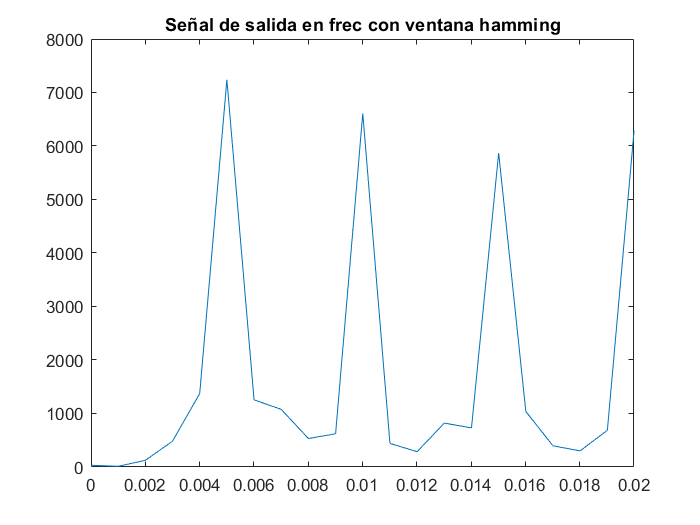

Nc=max(find(abs(hc)>max(hc)/20));
yci=filter(b,a,val);
yc=yci(Nc-1:end);
nc=linspace(0,N-Nc+1,N-Nc+2);
Ycw=DTFT(yc.*hamming(length(yc))',nc,w);
plot(w/pi,abs(Ycw)); title('Señal de salida en frec con ventana hamming')
xlim([0 0.02])

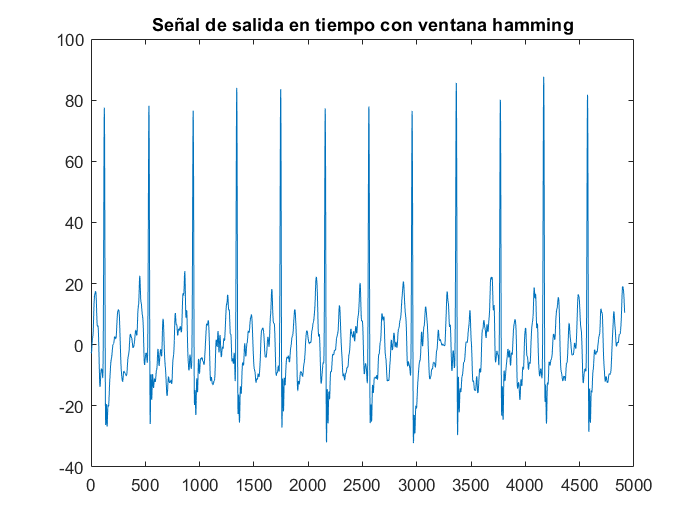

plot(real(yc)); title('Señal de salida en tiempo con ventana hamming')

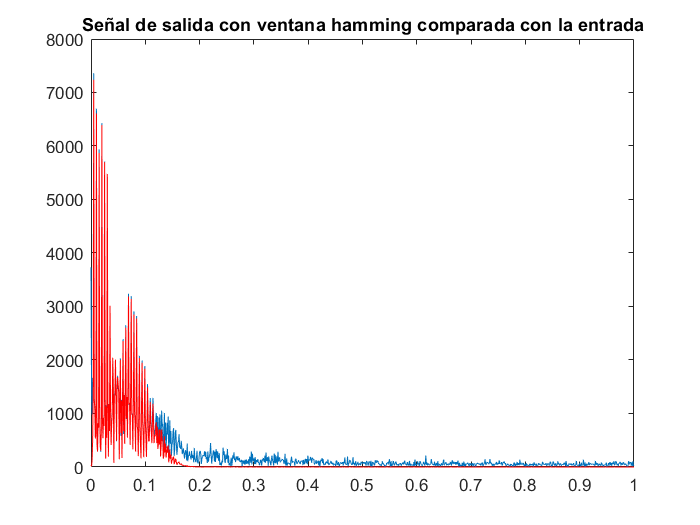

plot(w/pi,abs(Xw),w/pi,abs(Ycw),'r');title('Señal de salida con ventana hamming comparada con la entrada')

### 4- Detección de pulso 

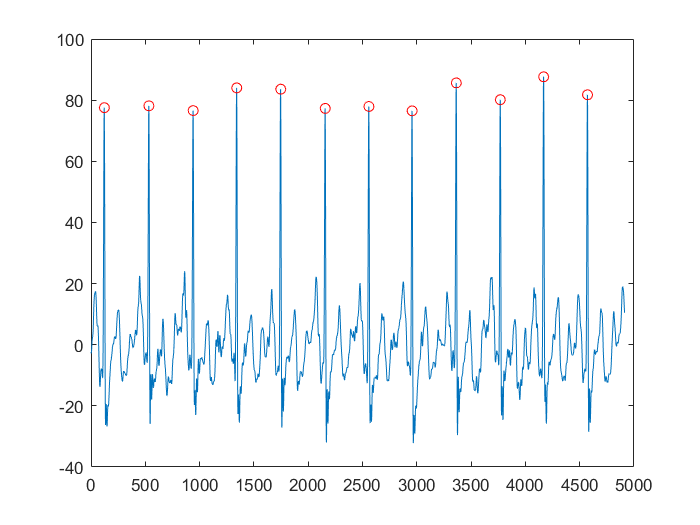

%Mediante detección de picos
[pks,locs] = findpeaks(yc,'MinPeakDistance',200,'MinPeakHeight',max(abs(yc)/2));
plot(nc,yc,locs,pks,'or');

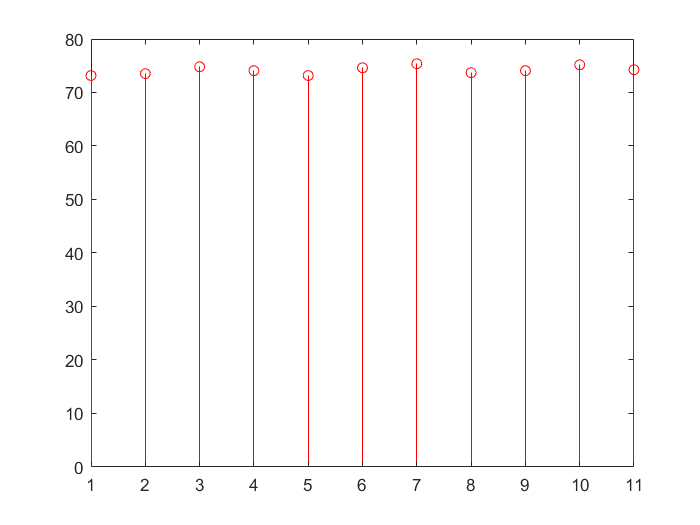

pulso = 60*fs./diff(locs);
stem(pulso,'r')%Por tanto, el pulso será de aproximadamente de 75 latidos/min

### 5- Trabajo adicional

#### 5.1- Histograma

La función de histograma aplicada al pulso, permite detectar sus irregularidades de una manera mas visual. 

No obstante, su aplicación tendría sentido en un a señal más duradera, ya que la que he escogido es de únicamente 10 segundos.

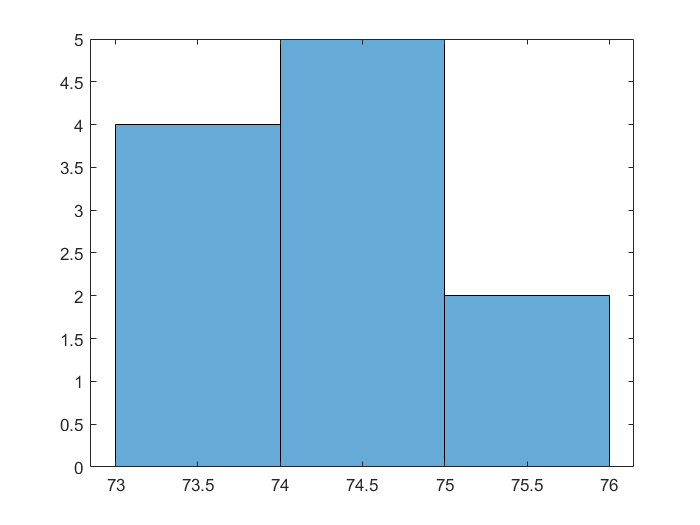

histogram(pulso)

#### 5.2- Variabilidad de la frecuencia cardiaca 

Es la variación en el tiempo que transcurre entre los intervalos RR del electrocardiograma (latidos) y refleja la actividad del sistema nervioso autónomo sobre la función cardíaca.

t1=(1:1:length(val))*(1/fs); 
R_loc_tiempo= t1(locs); %ubicación en el tiempo de los picos
HRV=diff(R_loc_tiempo); %calcular HRV

Para su determinación, un parámetro muy utilizado es el RMSSD ("Root Mean Square of the Successive Differences")

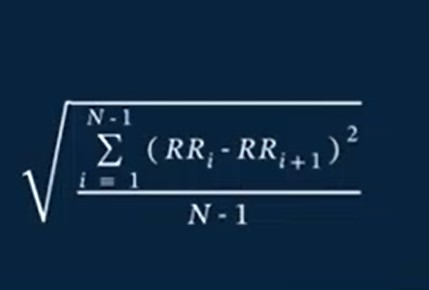

%RMSSD
resta_RR=diff(HRV);
resta_RR2=resta_RR.^2;
suma_resta_RR2=sum(resta_RR2);
normaliz=suma_resta_RR2/length(resta_RR);
%finalmente
RMSSD=sqrt(normaliz);
RMSSD_ms=RMSSD*1000 %Debemos pasarlo a ms

RMSSD_ms = 11.3137

En conclusión, esta medida consiste en un marcador fiable para analizar el estado psicofisiológico de una persona. 

Su valor depende de la edad y el género de la persona. Generalmente un valor mayor a 20 ms es indicativo de 

una buena variabilidad de la frecuencia cardíaca en personas jóvenes y saludables, y una más alta actividad parasimpática.

Sin embargo, como es el caso,  valores inferiores, hacen referencia a personas mayores con enfermedades crónicas. 

Cabe destacar que la interpretación objetiva y completa de estos valores, debe hacerse conjuntamente a otros parámetros.

Además de que quizá el hecho de que la señal sea tan corta, afecte en el resultado del RMSSD, pues es posible que el paciente estuviese más relajado en ese preciso instante, y por ello no sería un valor concluyente, sería necesario un periodo más extenso.